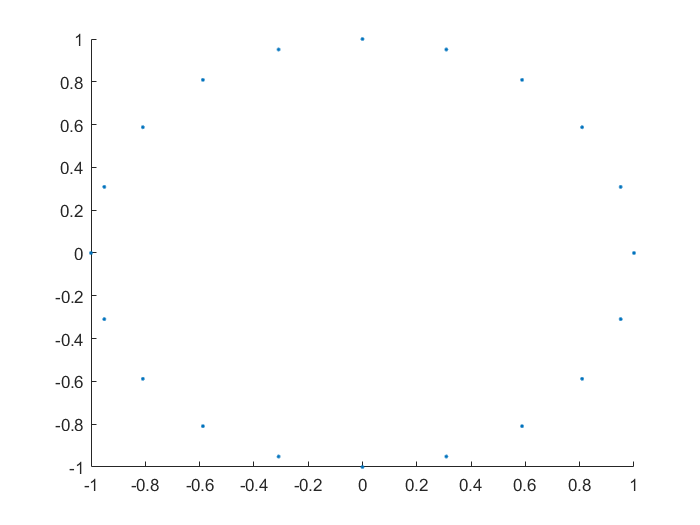

% A series test 2
count = 20;
theta = 0:(2*pi/count):2*pi;
% theta(end)=[];
Points = [cos(theta'),sin(theta')];
Normals = Points;
scatter(Points(:,1),Points(:,2),'.');

n = length(theta);

s=-0.5;
% a=0:0.1:5;
vk=5:1:10;
%a=1;

Maxtesterror1=zeros(length(vk),1);
Meantesterror1=zeros(length(vk),1);

for j=1:length(vk)
    kdtree = KDTreeSearcher(Points);
    k = vk(j)*ones(n,1);
    SupportSizes = zeros(n,1);
    distlist=SupportSizes;
    for i=1:n
        [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
        SupportSizes(i) = max(dists);
        distlist(i)=dists(2);
    end
    maxSupportSize = max(SupportSizes);
    % 生成局部坐标系，各点二次曲线
    [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
    ApproxArgs = zeros(n,1);
    meanerr=mean(Err);
    maxd=max(distlist);
    mind=min(distlist);
    distlist=(distlist-mind)/(maxd-mind);
    var=sum((Err-meanerr).^2)/n;
    meand=mean(distlist);
    vard=sum((distlist-meand).^2)/n;
    for i=1:n
        c = 1;
        for i1=1:n
            ApproxArgs(i1) = c;
        end
    end
    %%%计算对应的各个参数
    C = zeros(n,1);
    for i=1:n
        [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
        indices = indices{1};
        dists = dists{1};
        valsum = 0;
        rbfsum = 0;
        H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
        for j1=1:length(indices)
            if dists(j1)>=SupportSizes(indices(j1))
                continue
            end
            %Wendland part
%           value = rbf_wend(dists(j)/SupportSizes(indices(j)));
            %shepard part
%           value = rbf_shp(dists(j)/SupportSizes(indices(j)));
%           if(value==inf)
%               valsum=H(j);
%               rbfsum=1;
%               break;
%           end
            %Our method
            if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
                valsum = C(indices(j1))+H(j1);
                rbfsum = 1;
                break;
            end
            value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
        
            valsum = valsum - H(j1)*value;
            rbfsum = rbfsum + value;
        end
        C(i) = valsum/rbfsum;
    end
    f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
    res = 1000;
    restheta = 0:(2*pi/res):2*pi;
    respoints = [cos(restheta)',sin(restheta)'];
    F=zeros(length(restheta),1);
    for i=1:length(restheta)
        F(i)=f(respoints(i,1),respoints(i,2));
    end
    error2=abs(F);
    Maxtesterror1(j)=max(error2);
    Meantesterror1(j)=mean(error2);
end

% A series test 2
count = 20;
theta = 0:(2*pi/count):2*pi;
% theta(end)=[];
Points = [cos(theta'),sin(theta')];
Normals = Points;
scatter(Points(:,1),Points(:,2),'.');

n = length(theta);

s=-0.5;
% a=0:0.1:5;
%a=1;

Maxtesterror=zeros(length(vk),1);
Meantesterror=zeros(length(vk),1);

for j=1:length(vk)
    kdtree = KDTreeSearcher(Points);
    k = vk(j)*ones(n,1);
    distlist=zeros(n,1);
    mindist=distlist;
    for i=1:n
        [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
        SupportSizes(i) = max(dists);
        mindist(i)=dists(2);
        distlist(i)=(sum(dists)/k(i))/SupportSizes(i);
    end
    maxSupportSize = max(SupportSizes);
    ApproxArgs = zeros(n,1);
    % 生成局部坐标系，各点二次曲线
    [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
    meanerr=mean(Err);
    var=sum((Err-meanerr).^2)/n;
    meand=mean(distlist);
    vard=sum((distlist-meand).^2)/n;
    meanmd=mean(mindist);
    varmd=sum((mindist-meanmd).^2)/n;
    %%%计算对应的各个参数
    c=1;
    for i1=1:n
        ApproxArgs(i1) = c;
        if((mindist(i1)-meanmd)^2>3*varmd)
%             i1=i
            x=sqrt((mindist(i1)-meanmd)^2/(3*varmd));
            if((mindist(i1)-meanmd)<0)
                %越稠密，越逼近
                ApproxArgs(i1)=c*(x);
            else
                 %越稀疏，越插值
                ApproxArgs(i1)=c*(1/x);
            end
        elseif((distlist(i1)-meand)^2>3*vard)
            x=sqrt((distlist(i1)-meand)^2/(3*vard));
            if((distlist(i1)-meand)>0)
                ApproxArgs(i1)=c/x;
            else
                ApproxArgs(i1)=c*x;
            end
        elseif((Err(i1)-meanerr)^2>3*var)
            x=sqrt((Err(i1)-meanerr)^2/(3*var));
            if(Err(i)-meanerr>0)
                ApproxArgs(i1)=c/(x);
            else
                ApproxArgs(i1)=c*x;
            end
        end
    end


    %%%计算对应的各个参数
    C = zeros(n,1);
    for i=1:n
        [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
        indices = indices{1};
        dists = dists{1};
        valsum = 0;
        rbfsum = 0;
        H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
        for j1=1:length(indices)
            if dists(j1)>=SupportSizes(indices(j1))
                continue
            end
            %Wendland part
%           value = rbf_wend(dists(j)/SupportSizes(indices(j)));
            %shepard part
%           value = rbf_shp(dists(j)/SupportSizes(indices(j)));
%           if(value==inf)
%               valsum=H(j);
%               rbfsum=1;
%               break;
%           end
            %Our method
            if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
                valsum = C(indices(j1))+H(j1);
                rbfsum = 1;
                break;
            end
            value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
        
            valsum = valsum - H(j1)*value;
            rbfsum = rbfsum + value;
        end
        C(i) = valsum/rbfsum;
    end
    f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
    res = 1000;
    restheta = 0:(2*pi/res):2*pi;
    respoints = [cos(restheta)',sin(restheta)'];
    F=zeros(length(restheta),1);
    for i=1:length(restheta)
        F(i)=f(respoints(i,1),respoints(i,2));
    end
    error2=abs(F);
    Maxtesterror(j)=max(error2);
    Meantesterror(j)=mean(error2);
end

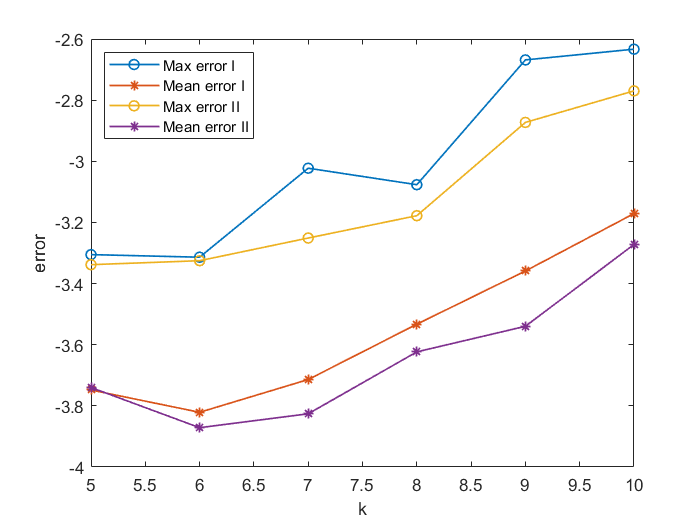

figure;
plot(vk,log10(Maxtesterror1),'-o',vk,log10(Meantesterror1), '*-','linewidth', 1);
hold on
plot(vk,log10(Maxtesterror),'-o',vk,log10(Meantesterror), '*-','linewidth', 1);
legend('Max error I','Mean error I','Max error II','Mean error II','Location','Northwest')
xlabel('k');ylabel('error');
hold off;